Proyecto

data = readtable('data/base/count_per_month.csv')

data = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Lectura de datos con archivos
countries = cell(1,7);
for continent = 1:length(continents{:,1})
    countries{continent} = {readtable(horzcat('./data/base/geographicCoverage_',replace(lower(continents{continent,1}{:}),' ','_'),'.csv'),'Delimiter',',')};
end
countries{7}{:,1}{:,1}
% lectura de countries para cargar en listbox 2
africa = readtable('./data/base/geographicCoverage_africa.csv')
table2array(africa)

% Probando con las fechas
%datetime(,'InputFormat','yyyy/MM/dd HH:mm:ss.S')
date = data{1,"releaseDate"}

date = 1×1 cell array
    {'2010-02'}


class(date)

ans = 'cell'

datetime(datatable{:,'releaseDate'},'InputFormat','yyyy-MM')

ans = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


% Probando la clase MobileAppDataset
objDatasetManager = MobileAppDataset()

objDataset =   MobileAppDataset with no properties.


objDatasetManager.getCountPerMonthTable()

ans = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Accediendo a datos con expresiones
datatable = objDatasetManager.getCountPerMonthTable();
datatable{1,'releaseDate'}{:}

ans = '2010-02'

% Método getCountPerMonth() de la clase MobileAppDataset
[fechas, cantidades] = objDatasetManager.getCountPerMonth()

fechas = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


cantidades =      1
     1
     1
     2
     1
     1
     1
     1
     1
     4


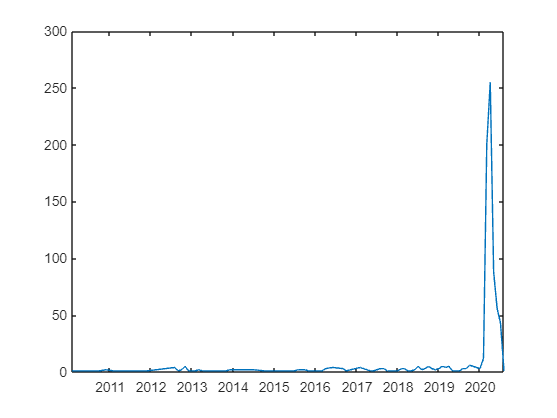

plot(fechas, cantidades)

% CONFIGURACIÓN de MATLAB con Python
pathExe = horzcat(pwd,'\env\Scripts\python.exe');
pyenv('Version',pathExe)

Error using pyenv
Python is loaded. The environment cannot be changed in this MATLAB session. To change the environment, restart MATLAB, and then call 'pyenv'.

%py.help('pandas')
py.help('print')

sysPath = py.sys.path;
pathMods = horzcat(pwd,'\src');
if count(sysPath,pathMods) == 0
    insert(sysPath,int32(0),pathMods)
end

% importar módulos
py.importlib.import_module('cargar_data')

ans =   Python module with properties:

    ubicaciones: [1×1 py.function]
      dataframe: [1×1 py.function]
             pd: [1×1 py.module]
             np: [1×1 py.module]

    <module 'cargar_data' from 'C:\\Users\\Tiber\\Mis Archivos\\Repositorios\\GitHub\\UTPL\\proyecto-final-b-da8ah\\src\\cargar_data.py'>


df = py.cargar_data.dataframe()

df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.datetimes.DatetimeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.numpy.int32]
      style: [1×1 py.pandas.io.formats.style.Styler]
     values: [1×1 py.numpy.ndarray]

                                      name  ...  status
    releaseDate                             ...        
    2010-02-04   Relief Centr

ubicaciones = py.cargar_data.ubicaciones(df)

ubicaciones =   Python list with no properties.

    [['WORLD', 'Africa', 'Asia', 'Europe', 'North America', 'Oceania', 'South America'], [['ALL', 'Algeria', 'Angola', 'Argentina', 'Armenia', 'Australia', 'Austria', 'Azerbaijan', 'Bahrain', 'Bangladesh', 'Bhutan', 'Bolivia', 'Bonaire', 'Brazil', 'Bulgaria', 'Cabo Verde', 'Cambodia', 'Canada', 'Chile', 'China', 'Colombia', 'Croatia', 'Cyprus', 'Czechia', 'Denmark', 'Dominican Republic', 'Ecuador', 'Egypt', 'France', 'Georgia', 'Germany', 'Ghana', 'Gibraltar', 'Guatemala', 'Hong Kong', 'Hungary', 'Iceland', 'India', 'Indonesia', 'Ireland', 'Israel', 'Italy', 'Jamaica', 'Japan', 'Jordan', 'Kazakhstan', 'Korea', 'Kuwait', 'Kyrgyzstan', "Lao People's Democratic Republic", 'Latvia', 'Lebanon', 'Liberia', 'Libya', 'Lithuania', 'Luxembourg', 'Malaysia', 'Maldives', 'Mali', 'Mauritius', 'Mexico', 'Mongolia', 'Myanmar', 'Nepal', 'Netherlands', 'New Zealand', 'Nigeria', 'North Macedo

world = ubicaciones{1}

world =   Python list with no properties.

    ['WORLD', 'Africa', 'Asia', 'Europe', 'North America', 'Oceania', 'South America']


char(world{1})

ans = 'WORLD'

% Integración de MATLAB con Python Exitosa (!)

P = pyenv

P =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\Tiber\Mis Archivos\Repositorios\GitHub\UTPL\proyecto-final-b-da8ah\env\Scripts\python.exe"
          Library: "C:\Users\Tiber\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\Tiber\Mis Archivos\Repositorios\GitHub\UTPL\proyecto-final-b-da8ah\env"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "11212"
      ProcessName: "MATLAB"


%system('matlab -r')
%quit;

% LECTURA DE DATOS
% lectura de continents para cargar en listbox 1
objDatasetManager = DatasetManager(pathMods);
%warning('off','MATLAB:table:ModifiedAndSavedVarnames');
objDatasetManager.isInit()

ans = logical
   1


continents = objDatasetManager.getContinents();
continents

continents = 1×7 string array
    "WORLD"    "Africa"    "Asia"    "Europe"    "North America"    "Oceania"    "South America"


continent = 7;
countries = objDatasetManager.getCountries(continent);
countries

countries = 1×8 string array
    "Argentina"    "Bolivia"    "Brazil"    "Chile"    "Colombia"    "Ecuador"    "Peru"    "Uruguay"


% consultas al dataframe
%consulta = objDatasetManager.filtrar('WORLD','ALL','Ambos','Ambos',2,1,1)
%result = {datetime(string(cell(consulta{1})),'InputFormat','yyy'),int32(py.array.array('i',consulta{2}))}
%result{1}
resultado = objDatasetManager.filtrar('WORLD','ALL','Ambos','Ambos',3,1,1)

resultado = 1×2 cell array
    {[2010    2011    2012    2013    2014    2015    2016    2017    2018    2019    2020]}    {[5 10 23 31 40 50 63 80 111 152 810]}


resultado{1}

ans = 1×11 datetime array
   2010   2011   2012   2013   2014   2015   2016   2017   2018   2019   2020
